clear;
clc;
[stage_lab,patient_label,patient_num]=get_stage('./data/UCEC_stage.txt');

     Stage      sample num
    ________    __________

    {'IA'  }       167    
    {'IB'  }       148    
    {'IC'  }        25    
    {'IIA' }         6    
    {'IIB' }        13    
    {'IIIA'}        40    
    {'IIIB'}         6    
    {'IV'  }        29    



# Load data

network_path='./data/UCEC_Gene_network.txt';
case_sample = readtable('./data/UCEC_tumor.txt');
case_sample=table2array(case_sample(:,2:end));
ref_sample=readtable('./data/UCEC_normal.txt');
ref_sample=table2array(ref_sample(:,2:end));

# Calculate local sPGGM of each center gene

tic
local_sPGGM = get_LocalsPGGM(case_sample,ref_sample,network_path);

total gene num:13501; total center gene num(center node num):7903
Sample 1 is finished.
Sample 2 is finished.
Sample 3 is finished.
Sample 4 is finished.
Sample 5 is finished.
Sample 6 is finished.
Sample 7 is finished.
Sample 8 is finished.
Sample 9 is finished.
Sample 10 is finished.
Sample 11 is finished.
Sample 12 is finished.
Sample 13 is finished.
Sample 14 is finished.
Sample 15 is finished.
Sample 16 is finished.
Sample 17 is finished.
Sample 18 is finished.
Sample 19 is finished.
Sample 20 is finished.
Sample 21 is finished.
Sample 22 is finished.
Sample 23 is finished.
Sample 24 is finished.
Sample 25 is finished.
Sample 26 is finished.
Sample 27 is finished.
Sample 28 is finished.
Sample 29 is finished.
Sample 30 is finished.
Sample 31 is finished.
Sample 32 is finished.
Sample 33 is finished.
Sample 34 is finished.
Sample 35 is finished.
Sample 36 is finished.
Sample 37 is finished.
Sample 38 is finished.
Sample 39 is finished.
Sample 40 is finished.
Sample 41 is finished.


toc

历时 12056.132221 秒。


# Identify critical points by calculating the global sPGGM

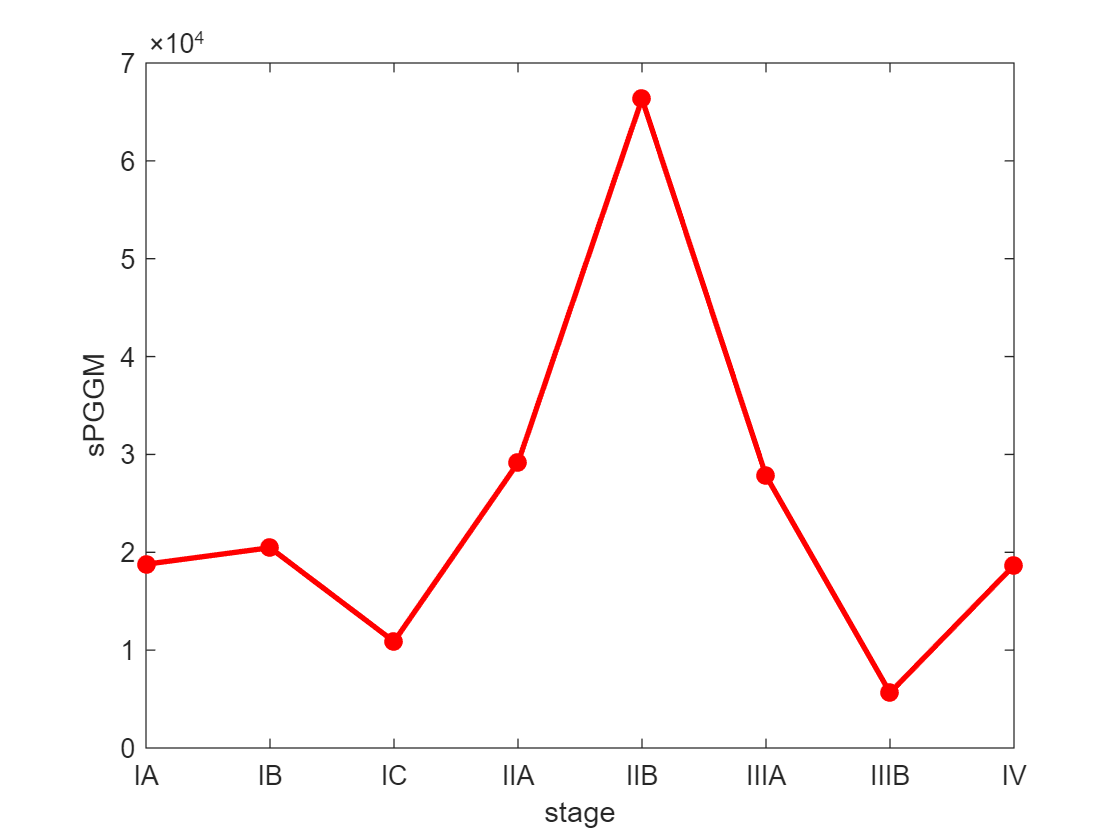

count=ceil(0.05*size(ref_sample,1));
stage_num=length(stage_lab);
sPGGM = calc_GlobalsPGGM(local_sPGGM,count,patient_label,patient_num);
plot(1:stage_num,sPGGM,'r-o','markersize',5,'LineWidth',2,'MarkerFaceColor','r')
xticks(1:stage_num)
xticklabels(stage_lab)
xlabel('stage')
ylabel('sPGGM');